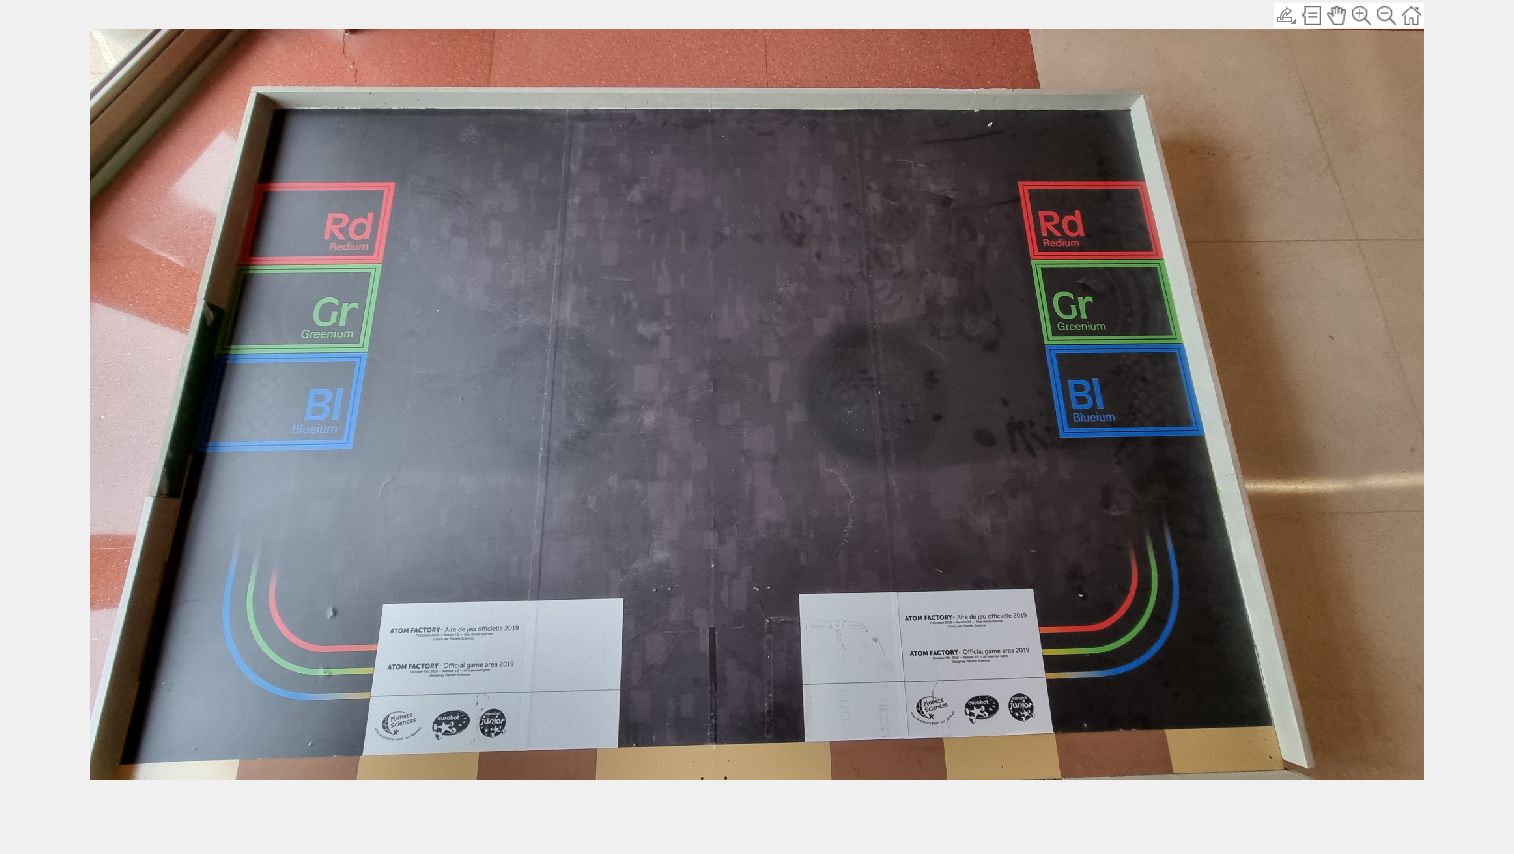

% 1. Cargamos la imagen
I = imread('.\imagenes\pista.jpg');

% 2. Calculamos los puntos de la carta de poquer a la salida
dstPoints = [0 0; 3000 0; 3000 2000; 0 2000];

% 3. Capturamos los puntos de entrada de la carta y estimamos la
% transformacion de perspectiva
figure
[x, y, P] = impixel(I);

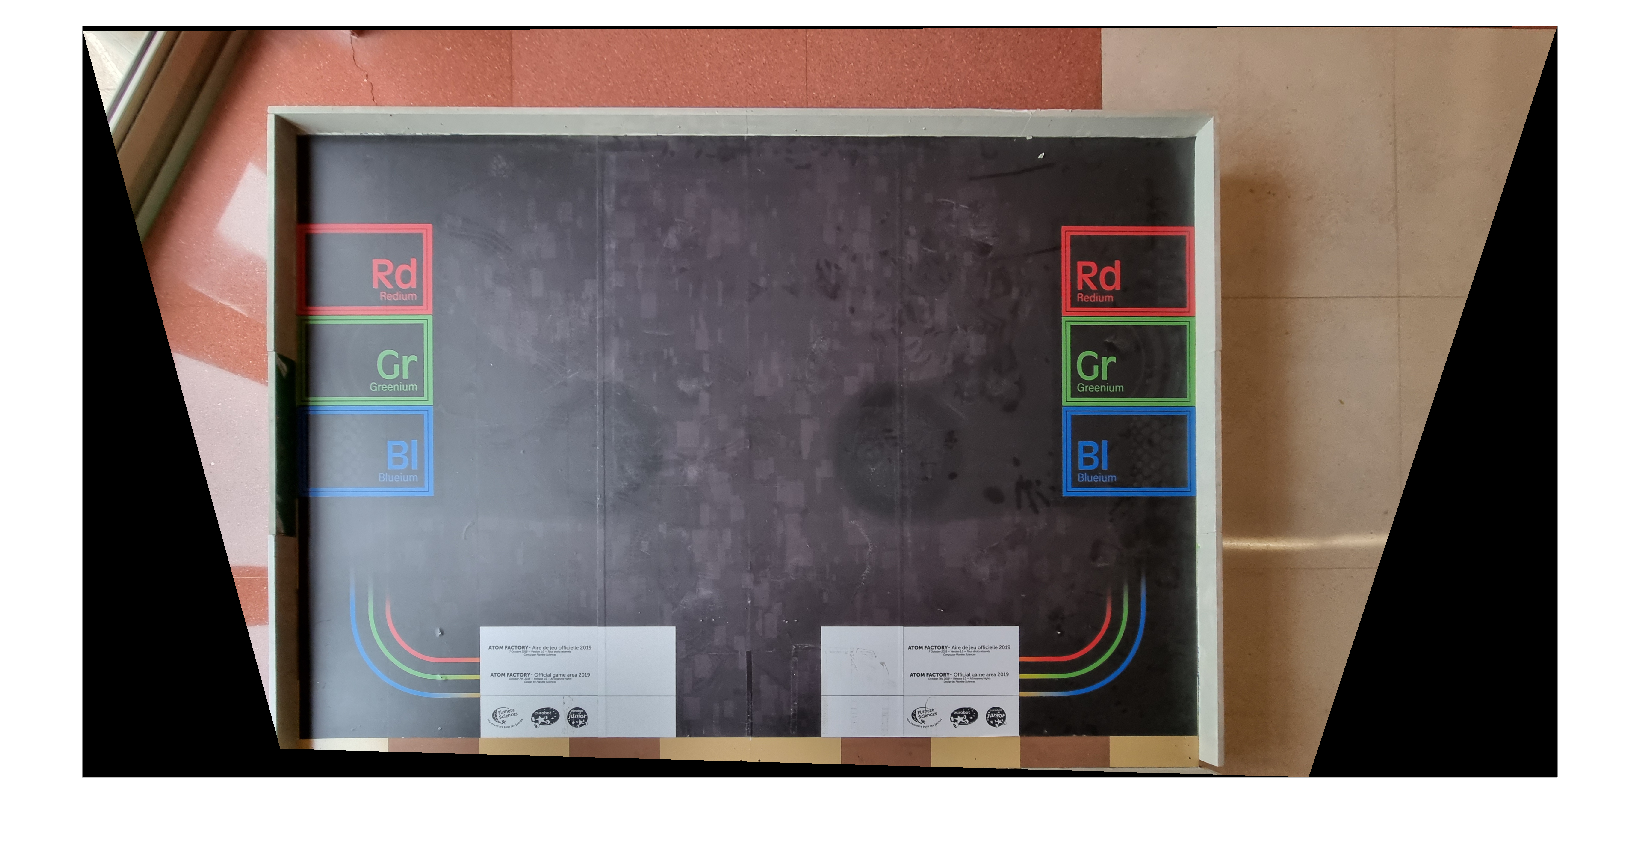


srcPoints = [x y];
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'projective');

% 4. Aplicamos la transformacion de perspectiva
destino = imwarp(I,tform);

% 5. Mostramos el resultado
figure; imshow(destino);